# Chap 10. Unsupervised Learning

## 10.4 Lab 1: Principal Components Analysis

Functions:  [pca](https://www.mathworks.com/help/stats/pca.html), [biplot](https://www.mathworks.com/help/releases/R2019b/stats/biplot.html)

clear all; clc; close all;
USArrests = readtable("Data\USArrests.csv", 'TreatAsEmpty',{'?','NA','N/A'},'ReadRowNames', true);

The rows of the data set contain the 50 states, in alphabetical order. 

states = USArrests.Properties.RowNames

states = 50×1 cell array
    {'Alabama'      }
    {'Alaska'       }
    {'Arizona'      }
    {'Arkansas'     }
    {'California'   }
    {'Colorado'     }
    {'Connecticut'  }
    {'Delaware'     }
    {'Florida'      }
    {'Georgia'      }
    {'Hawaii'       }
    {'Idaho'        }
    {'Illinois'     }
    {'Indiana'      }
    {'Iowa'         }
    {'Kansas'       }
    {'Kentucky'     }
    {'Louisiana'    }
    {'Maine'        }
    {'Maryland'     }
    {'Massachusetts'}
    {'Michigan'     }
    {'Minnesota'    }
    {'Mississippi'  }
    {'Missouri'     }
    {'Montana'      }
    {'Nebraska'     }
    {'Nevada'       }
    {'New Hampshire'}
    {'New Jersey'   }


The columns of the data set contain the four variables.

USArrests.Properties.VariableNames

ans = 1×4 cell array
    {'Murder'}    {'Assault'}    {'UrbanPop'}    {'Rape'}


Compute the mean of the four variables

array2table(mean(USArrests{:,:},1),'VariableNames',USArrests.Properties.VariableNames)

ans = 1×4 table
    Murder    Assault    UrbanPop     Rape 
    ______    _______    ________    ______

    7.788     170.76      65.54      21.232


Compute the variances of the four variables

array2table(var(USArrests{:,:},1),'VariableNames',USArrests.Properties.VariableNames)

ans = 1×4 table
    Murder    Assault    UrbanPop     Rape 
    ______    _______    ________    ______

    18.591    6806.3      205.33     85.975


Normalizes each column observed data X, using the  [normalize](https://www.mathworks.com/help/releases/R2019b/matlab/ref/double.normalize.html) or [`cluster`](https://www.mathworks.com/help/stats/cluster.html) function

X = normalize(USArrests{:,:},1);
% or
% X = zscore(USArrests{:,:},1);

Perform principal component analysis using the ALS algorithm and display the component coefficients.

[coeff,score,latent,~,explained,mu] = pca(X);

Compute the means and standard deviations of the variables that were used for scaling prior to implementing PCA.

mean(USArrests{:,:},1)

ans =     7.7880  170.7600   65.5400   21.2320


std(USArrests{:,:},1)

ans =     4.3117   82.5001   14.3293    9.2722


Compute the principal component loadings

coeff

coeff =     0.5359   -0.4182   -0.3412   -0.6492
    0.5832   -0.1880   -0.2681    0.7434
    0.2782    0.8728   -0.3780   -0.1339
    0.5434    0.1673    0.8178   -0.0890


Compute size of the principal component score vectors

size(score)

ans =     50     4


Reconstruct the normalized observed data X

Xrec = score*coeff' + repmat(mu,size(X,1),1);

Reconstruct the observed data 

% Xcentered = score*coeff';
Xmean = mean(USArrests{:,:});
Xstd = std(USArrests{:,:});
% Xreturn = Xrec.*Xstd + Xmean
Xreturn = Xrec*diag(Xstd) + repmat(Xmean,size(X,1),1);

Create biplot of the observations in the space of the first 4 principal components, observation labels and variable labels in a single plot.

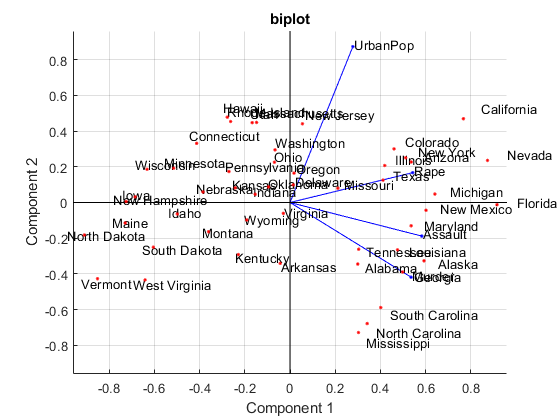

figure
biplot1(coeff(:,1:2),'scores',score(:,1:2),...
    'ObsLabels',USArrests.Properties.RowNames,...
    'varlabels',USArrests.Properties.VariableNames);
title('biplot');

Compute the standard deviations by each principal component

latent'.^0.5

ans =     1.5749    0.9949    0.5971    0.4164


The variance explained by each principal component

latent'

ans =     2.4802    0.9898    0.3566    0.1734


The proportion of variance explained by each principal component

explained'/100

ans =     0.6201    0.2474    0.0891    0.0434


Plot the PVE explained by each component

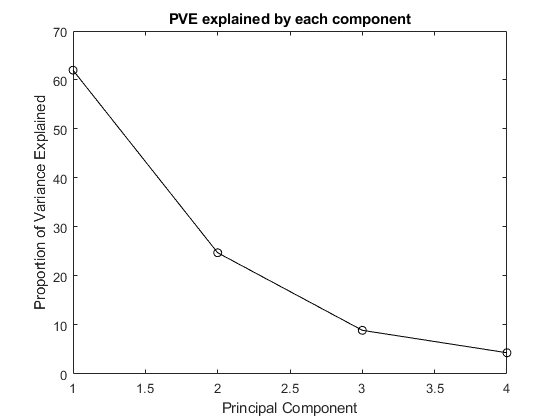

figure
plot((1:size(X,2)),explained,'Marker','o','Color','k');
xlabel('Principal Component'); 
ylabel('Proportion of Variance Explained');
title('PVE explained by each component');

Plot the cumulative PVE explained by each component

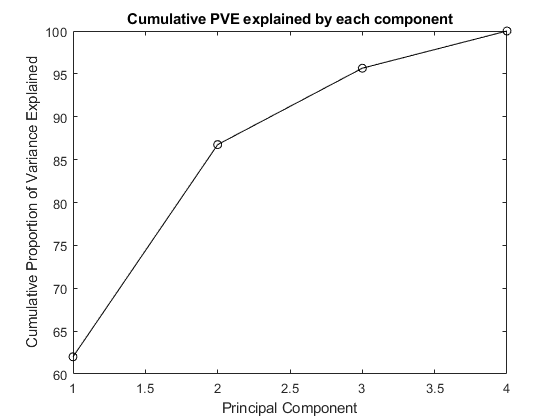

figure
plot((1:size(X,2)),cumsum(explained),'Marker','o','Color','k');
xlabel('Principal Component'); 
ylabel('Cumulative Proportion of Variance Explained');
title('Cumulative PVE explained by each component');

## 10.5 Lab 2: Clustering

### 10.5.1 K-Means Clustering

[`kmeans`](https://www.mathworks.com/help/stats/kmeans.html)

clear all; clc; close all;

Randomly Generated Data

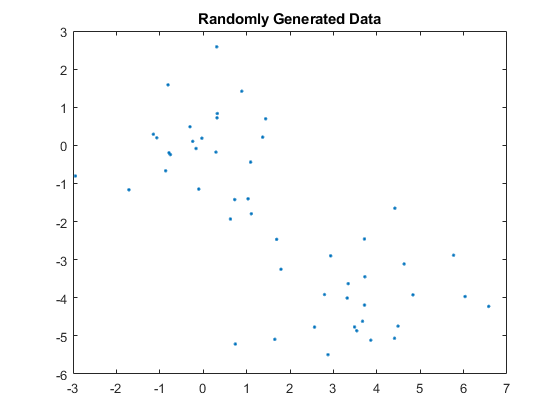

rng default; % For reproducibility
x = randn(50,2);
x(1:25,1) = x(1:25,1) + 3;
x(1:25,2) = x(1:25,2) - 4;
figure;
plot(x(:,1),x(:,2),'.');
title 'Randomly Generated Data';

Partition the training data into 2 clusters by using [`kmeans`](https://www.mathworks.com/help/stats/kmeans.html).

kmOut = kmeans(x,2,'Replicates',20);

Obtain the cluster assignments of the 50 observations

kmOut'

ans =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


Plot the clusters and the cluster centroids.

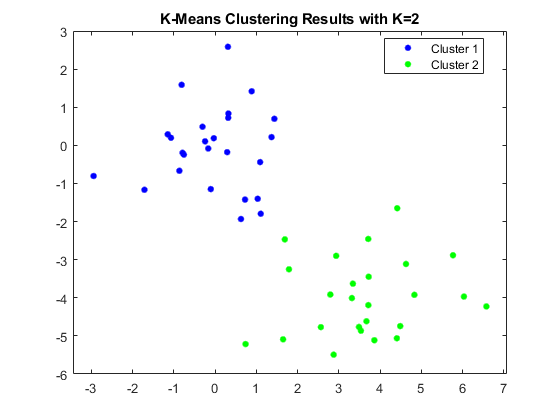

figure
gscatter(x(:,1),x(:,2),kmOut,'bgm');
legend({'Cluster 1','Cluster 2'},'Location','best');
title 'K-Means Clustering Results with K=2'

Partition the training data into 3 clusters by using [`kmeans`](https://www.mathworks.com/help/stats/kmeans.html).

rng default; % For reproducibility
[kmOut, kmMean,sumd,D] = kmeans(x,3,'Replicates',20);

K-means clustering with 3 clusters of sizes

summary(categorical(kmOut))

     1       7 
     2      25 
     3      18 


`Cluster means:`

kmMean

kmMean =     5.1398   -3.1736
   -0.0556   -0.0858
    3.0341   -4.3074


`Clustering vector:`

kmOut'

ans =      3     1     3     3     3     3     3     3     1     1     3     1     3     3     1     3     3     3     3     1     3     3     3     1     3     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


Within-cluster sums of point-to-centroid distances

sumd'

ans =    11.3979   54.5476   30.5190


Total within-cluster sum of squares by cluster

sum(sumd)

ans = 96.4645

Plot the clusters

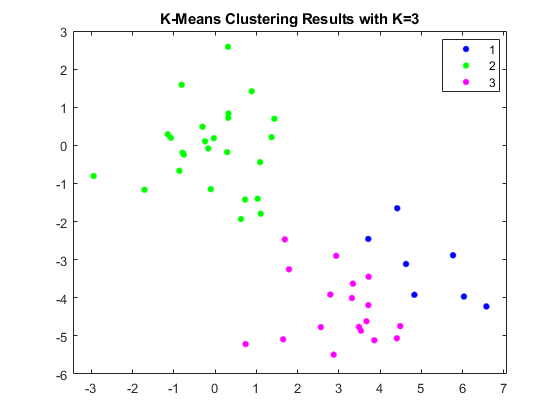

figure
gscatter(x(:,1),x(:,2),kmOut,'bgm');
title 'K-Means Clustering Results with K=3'

Compare Total within-cluster sum of squares by cluster using *Replicates = *1 and *Replicates = *50

[~,~,sumd] = kmeans(x,3,'Replicates',1);
sum(sumd)

ans = 102.4865

[~,~,sumd] = kmeans(x,3,'Replicates',50);
sum(sumd)

ans = 96.4645

### 10.5.2 Hierarchical Clustering

## [Hierarchical Clustering](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

The [pdist](https://www.mathworks.com/help/stats/pdist.html) function returns this distance information in a vector, where each element contains the distance between a pair of objects.

distance = pdist(x,'euclidean')

distance =     1.6018    2.8184    0.4095    0.8843    3.0245    0.9758    1.2503    3.1070    2.9842    1.9010    2.6532    1.4286    2.0541    2.4144    1.2055    0.9123    0.9597    0.8936    3.3323    0.2819    2.3755    0.6948    2.0650    0.1102    4.2715    4.4433    6.5876    5.6994    6.3633    6.8187    6.9659    6.8439    7.7793    7.6481    5.9434    6.5418    6.3064    5.5224    6.4209    5.2015    6.2424    6.4468    8.1172    6.0824    6.1839    6.0472    4.1299    5.0550    3.9135    4.2917


Reformat the distance vector into a matrix using the [`squareform`](https://www.mathworks.com/help/stats/squareform.html) function.

squareform(distance);

Create a hierarchical cluster tree, using the [`linkage`](https://www.mathworks.com/help/stats/linkage.html) function

ZComplete = linkage(distance,'complete');
ZAverage = linkage(distance,'average');
ZSingle = linkage(distance,'single');

Create a [dendrogram](https://www.mathworks.com/help/releases/R2019b/stats/dendrogram.html) plot of `Z`. 

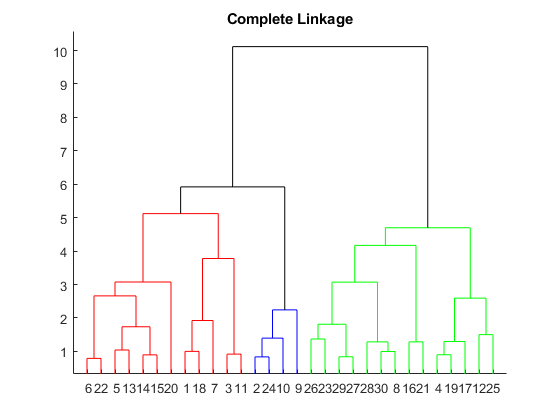

figure
dendrogram(ZComplete,'ColorThreshold',...
    median([ZComplete(end-2,3) ZComplete(end-1,3)]));
title 'Complete Linkage'

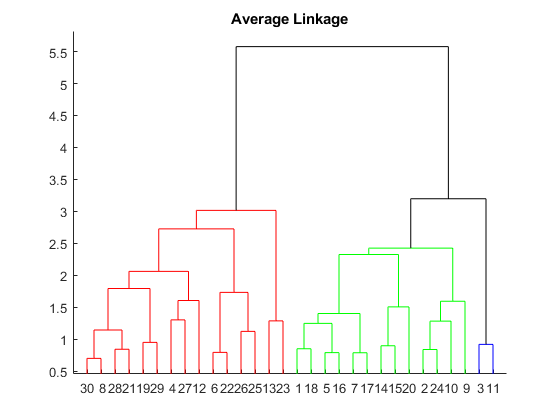

figure
dendrogram(ZAverage,'ColorThreshold',...
    median([ZAverage(end-2,3) ZAverage(end-1,3)]));
title 'Average Linkage'

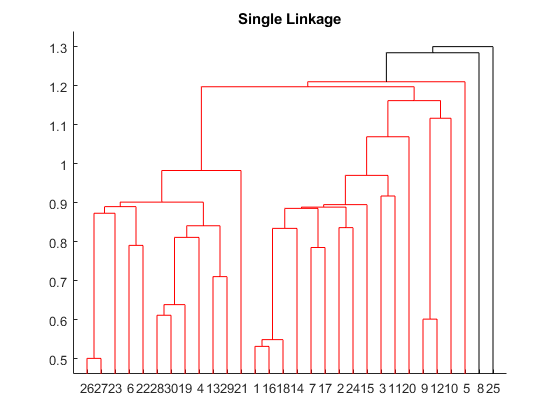

figure
dendrogram(ZSingle,'ColorThreshold',...
    median([ZSingle(end-2,3) ZSingle(end-1,3)]));
title 'Single Linkage'

Prune (cắt) the tree to partition your data into 2 clusters using the [`cluster`](https://www.mathworks.com/help/stats/cluster.html) function

TComplete = cluster(ZComplete,'maxclust',2).'

TComplete =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


TAverage = cluster(ZAverage,'maxclust',2).'

TAverage =      2     2     2     2     2     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


TSingle = cluster(ZSingle,'maxclust',2).'

TSingle =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     2     2     2     2     2     2


TSingle = cluster(ZSingle,'maxclust',4).'

TSingle =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     1     3     2     2     2     2     2     2     2     2     4     2     2     2     2     2     2


To scale the variables before performing hierarchical clustering of the observations, we use the [zscore](https://www.mathworks.com/help/releases/R2019b/stats/zscore.html) function:

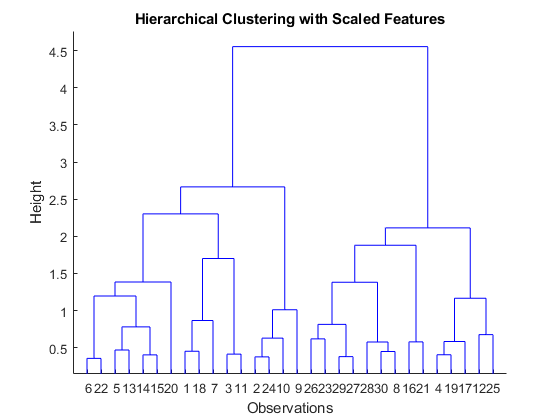

xsc = zscore(x);
dendrogram(linkage(xsc,'complete'));
title 'Hierarchical Clustering with Scaled Features'
xlabel 'Observations';
ylabel 'Height';

Complete Linkage with Correlation-Based Distance

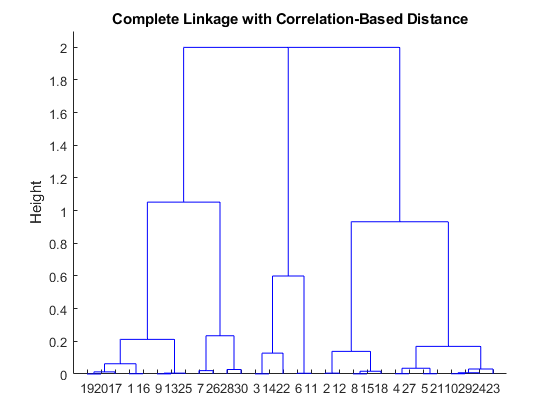

rng default; % For reproducibility
x = randn(30,3);
dd = pdist(x,'correlation');
dendrogram(linkage(dd,'complete'));
title 'Complete Linkage with Correlation-Based Distance'
ylabel 'Height';

## 10.6 Lab 3: NCI60 Data Example

The NCI60 data

clear all; clc; close all;
nciData = readtable('Data\NCI60_X.csv','ReadRowNames', true,'ReadVariableNames',true);

nciData = nciData{:,:};
nciLabels = readtable('Data\NCI60_y.csv','ReadRowNames', true);
nciLabels = nciLabels.x;
size(nciData)

ans =           64        6830


nciLabels(1:4).'

ans = 1×4 cell array
    {'CNS'}    {'CNS'}    {'CNS'}    {'RENAL'}


summary(categorical(nciLabels))

     BREAST           7 
     CNS              5 
     COLON            7 
     K562A-repro      1 
     K562B-repro      1 
     LEUKEMIA         6 
     MCF7A-repro      1 
     MCF7D-repro      1 
     MELANOMA         8 
     NSCLC            9 
     OVARIAN          6 
     PROSTATE         2 
     RENAL            9 
     UNKNOWN          1 


### 10.6.1 PCA on the NCI60 Data

Perform principal component analysis using the ALS algorithm using [pca](https://www.mathworks.com/help/releases/R2019b/stats/pca.html) function

[coeff,score,~,~,explained,~] = pca(zscore(nciData));

Plot projections of the NCI60 cancer cell lines onto the first three principal components

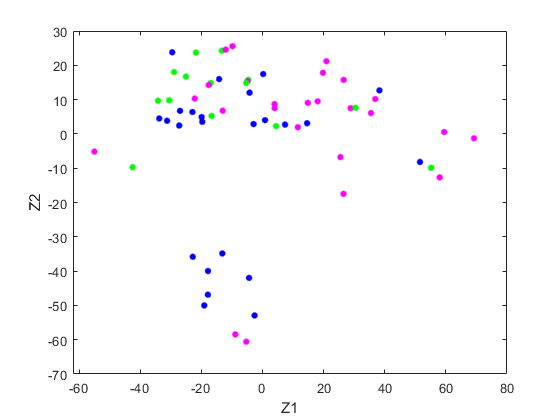

figure
gscatter(-score(:,1),-score(:,2),nciLabels,'bgm')
legend('off');
xlabel 'Z1'; ylabel 'Z2';

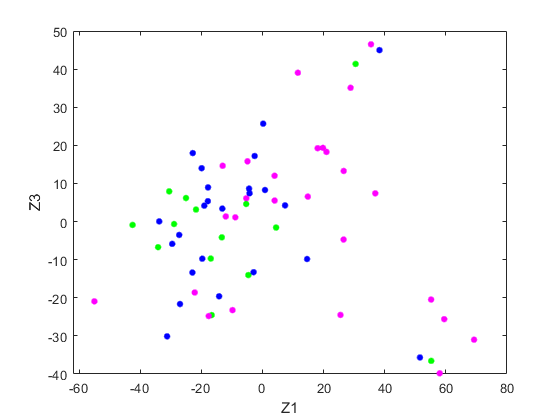

figure
gscatter(-score(:,1),score(:,3),nciLabels,'bgm')
legend('off');
xlabel 'Z1'; ylabel 'Z3';

Obtain a summary of the Standard deviation, Proportion of Variance và Cumulative Proportion of the principal components

num = cellstr(num2str((1:size(score,2)).'));
summary = array2table([std(score); explained'/100; cumsum(explained'/100)],...
            'VariableNames',strcat({'PC'},num),...
            'RowNames',{'Standard deviation','Proportion of Variance','Cumulative Proportion'})        

summary = 3×63 table
                               PC 1        PC 2        PC 3        PC 4       PC 5        PC 6        PC 7        PC 8        PC 9        PC10        PC11        PC12        PC13        PC14        PC15        PC16        PC17        PC18        PC19        PC20        PC21        PC22        PC23        PC24        PC25        PC26       PC27        PC28       PC29       PC30        PC31        PC32        PC33   

Plot the variance explained by the first 10 principal components

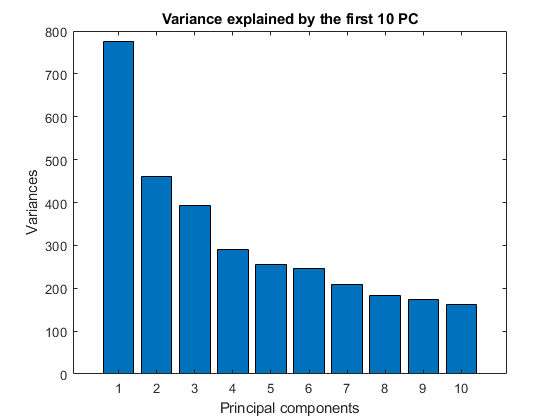

figure
bar((1:10),var(score(:,1:10)));
xlabel 'Principal components';
ylabel 'Variances';
title 'Variance explained by the first 10 PC';

Plot the PVE explained by each component

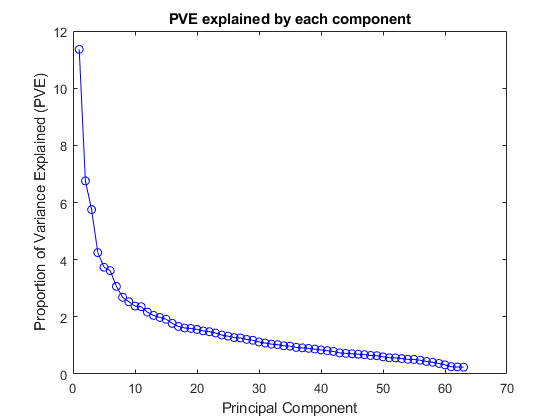

figure
plot((1:length(explained)),explained,'Marker','o','Color','b');
xlabel('Principal Component'); 
ylabel('Proportion of Variance Explained (PVE)');
title('PVE explained by each component');

Plot the cumulative PVE explained by each component

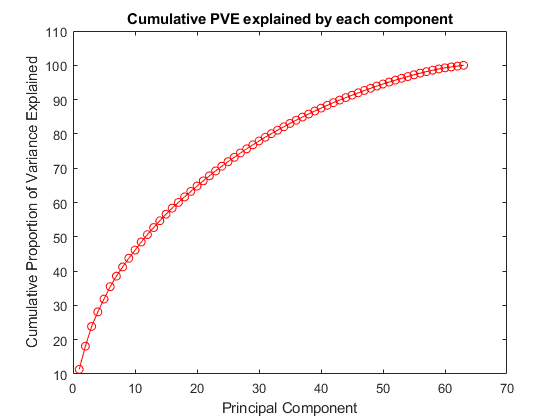

figure
plot((1:length(explained)),cumsum(explained),'Marker','o','Color','r');
xlabel('Principal Component'); 
ylabel('Cumulative Proportion of Variance Explained');
title('Cumulative PVE explained by each component');

### 10.6.2 Clustering the Observations of the NCI60 Data

To scale the variables before performing hierarchical clustering of the observations, we use the [zscore](https://www.mathworks.com/help/releases/R2019b/stats/zscore.html) function:

sdData = zscore(nciData);

Perform hierarchical clustering of the observations using complete, single, and average linkage. Euclidean distance is used as the dissimilarity measure.

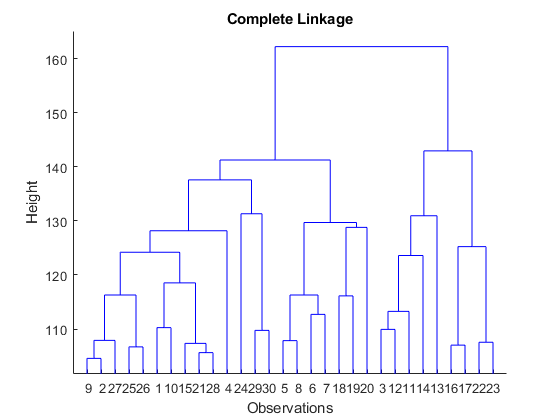

dendrogram(linkage(sdData,'complete','euclidean'));
title 'Complete Linkage'
xlabel 'Observations';
ylabel 'Height';

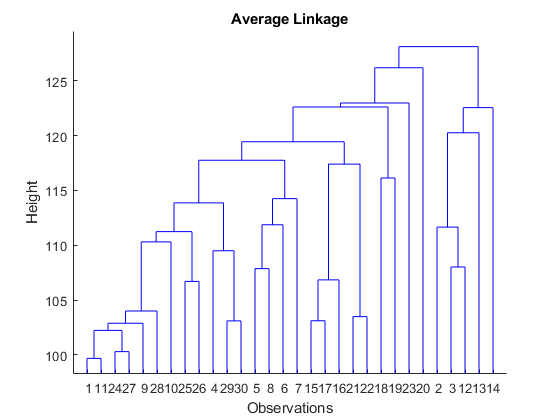

dendrogram(linkage(sdData,'average','euclidean'));
title 'Average Linkage'
xlabel 'Observations';
ylabel 'Height';

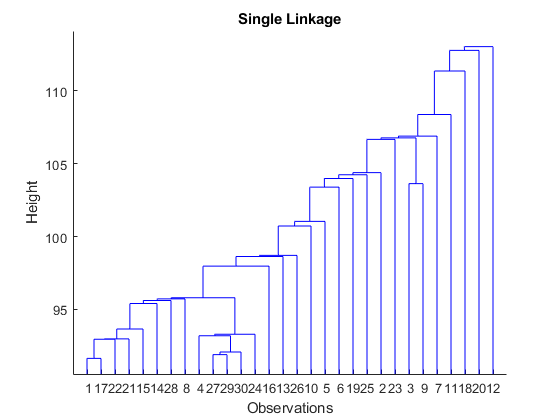

dendrogram(linkage(sdData,'single','euclidean'));
title 'Single Linkage'
xlabel 'Observations';
ylabel 'Height';

Cut the dendrogram at the height that will yield a particular number of clusters, say four: 

hcClusters = cluster(linkage(sdData,'complete','euclidean'),'maxclust',4);
confusiontable(hcClusters,nciLabels)

ans = 4×14 table
                     nciLabels. CNS    nciLabels. RENAL    nciLabels. BREAST    nciLabels. NSCLC    nciLabels. UNKNOWN    nciLabels. OVARIAN    nciLabels. MELANOMA    nciLabels. PROSTATE    nciLabels. LEUKEMIA    nciLabels. K562B-repro    nciLabels. K562A-repro    nciLabels. COLON    nciLabels. MCF7A-repro    nciLabels. MCF7D-repro
                     ______________    ________________    _________________    ________________    __________________    __________________    ___________________    ___________________    ___________________    ______________________    <s

Plot the cut on the dendrogram that produces these four clusters:

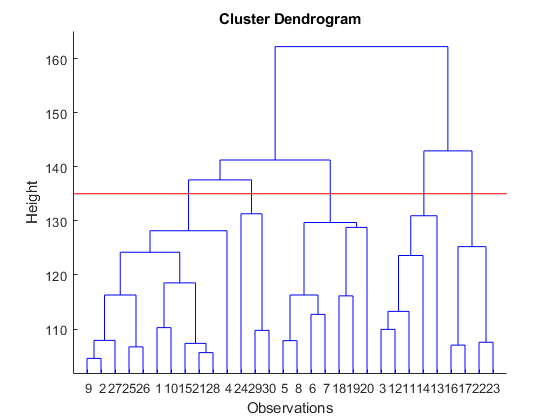

dendrogram(linkage(sdData,'complete','euclidean'));
hold on;
line(xlim,[135 135],'color','r');
title 'Cluster Dendrogram'
xlabel 'Observations';
ylabel 'Height';
hold off

Perform K-means clustering with K = 4

rng default; % For reproducibility
kmClusters = kmeans(sdData,4,'Replicates',20);
confusiontable(kmClusters,hcClusters)

ans = 4×4 table
                     hcClusters. 1    hcClusters. 2    hcClusters. 3    hcClusters. 4
                     _____________    _____________    _____________    _____________

    kmClusters. 1          0               15                9                0      
    kmClusters. 2          0               10                0                0      
    kmClusters. 3          7               15                0                0      
    kmClusters. 4          0                0                0                8      


Performing hierarchical clustering on the first 5 principal component score vectors

hcOut = linkage(pdist(score(:,1:5)),'complete');

Create a [dendrogram](https://www.mathworks.com/help/releases/R2019b/stats/dendrogram.html) plot of `Z`. 

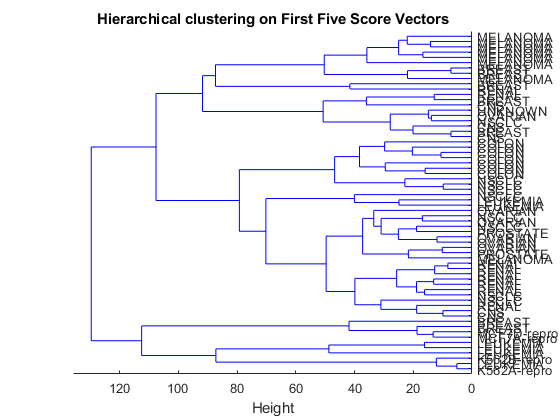

figure
dendrogram(hcOut,0,'Labels',nciLabels,'orientation', 'left');
title 'Hierarchical clustering on First Five Score Vectors'
xlabel 'Height';

hcClustersPCA = cluster(hcOut,'maxclust',4);
confusiontable(hcClustersPCA,nciLabels)

ans = 4×14 table
                        nciLabels. CNS    nciLabels. RENAL    nciLabels. BREAST    nciLabels. NSCLC    nciLabels. UNKNOWN    nciLabels. OVARIAN    nciLabels. MELANOMA    nciLabels. PROSTATE    nciLabels. LEUKEMIA    nciLabels. K562B-repro    nciLabels. K562A-repro    nciLabels. COLON    nciLabels. MCF7A-repro    nciLabels. MCF7D-repro
                        ______________    ________________    _________________    ________________    __________________    __________________    ___________________    ___________________    ___________________    ______________________